# Ejercicio 4.5

**Jose Antonio Lorencio Abril**

Primero, introducimos los datos del problema:

porcentajes = [0.45, 0.47, 0.53, 0.6, 0.66];
long = length(porcentajes);
quin = 0 : long-1;

Y los ploteamos:

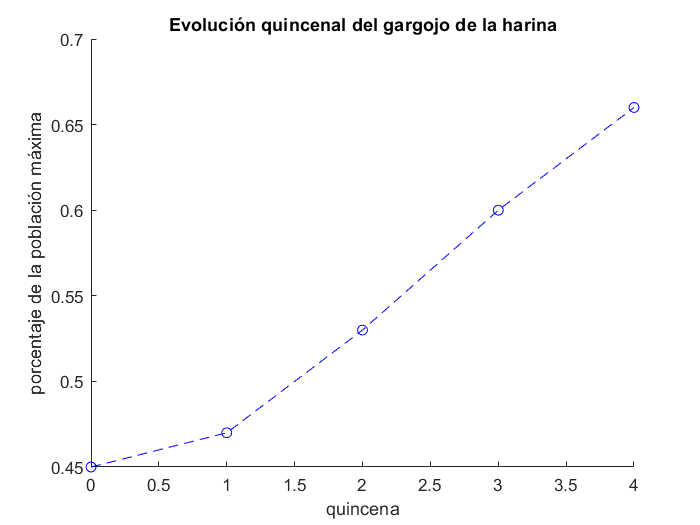

figure(1)
hold on
plot(quin, porcentajes, 'o--b')
title('Evolución quincenal del gargojo de la harina')
xlabel('quincena')
ylabel('porcentaje de la población máxima')
hold off

Tenemos la siguiente función de generación de la sucesión:


$$\(f(x)=s\cdot x\cdot e^{-x}\cdot\frac{x}{x+m}\)$$


Si tomamos $n\in\{1,..,4\}$, podemos hacer la siguiente transformación:


$$\(u_n = \frac{x_n\cdot e^{-x_n}}{x_{n+1}} = \frac{x_n \cdot e^{-x_n}}{f(x_n)} =  \)$$



$$\(=\frac{x_n+m}{x\cdot x_n} = \frac{1}{s}+\frac{m}{s\cdot x_n}\)$$


Y esto es lineal, por lo que esta transformación sirve:

pini = porcentajes(1:(long-1));
pfin = porcentajes(2:long);
c = pini.*exp(-pini)./pfin;

coef = polyfit(1./pini, c, 1)

coef =     0.1817    0.1870


Y aquí tenemos que $coef=[A,B]$, con $B=\frac{1}{s}$ y $A=\frac{m}{s}$. Por tanto:

s = 1/coef(2)

s = 5.3485

m = coef(1)*s

m = 0.9716

Y ahora definimos la función:

f = @(x) s.*x.*exp(-x).*x./(x+m);

Veamos ahora cómo se ajusta a los datos:

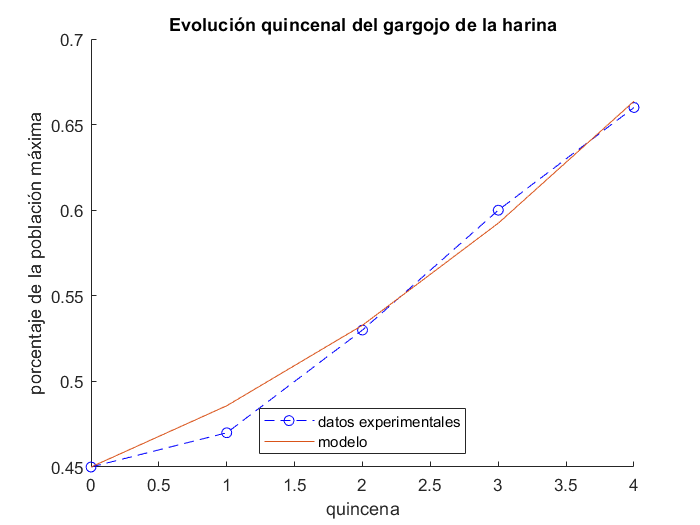

figure(2)
hold on
plot(quin, porcentajes, 'o--b')
plot(quin, iteracion(f,0.45,4), '-');
legend('datos experimentales', 'modelo', 'Location', 'south')
title('Evolución quincenal del gargojo de la harina')
xlabel('quincena')
ylabel('porcentaje de la población máxima')
hold off

Y el ajuste es decente.

Veamos ahora que se verifican las condiciones del ejercicio 4.4 (numéricamente).

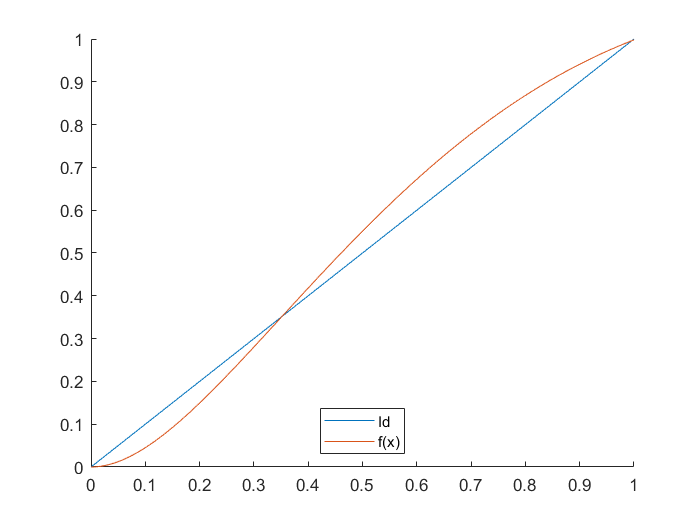

n=1000;
x = 0:n;
x = x/n;

figure(3)
hold on
plot(x,x);
plot(x, f(x));
legend('Id', 'f(x)', 'location', 'south');
hold off

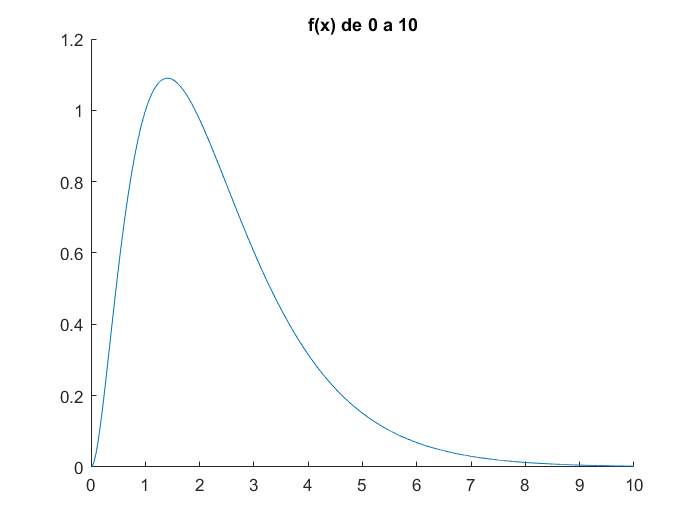


z = 0:10*n;
z = z/n;

figure(4)
hold on
plot(z, f(z));
title('f(x) de 0 a 10');
hold off

#### 1-

Vemos como, efectivamente, tiene 3 puntos fijos, que son el 0, un punto cercano a 1 y otro alrededor de 0.35. 

syms u;
p0 = vpasolve(f(u)==u, u,0)

$$p0 = 0$$

pU = vpasolve(f(u)==u, u,0.35)

$$pU = 0.35169637186791841857577339609636$$

pV = vpasolve(f(u)==u, u,1)

$$pV = 0.99597409067124538689780091412505$$

#### 2-

Vamos a calcular la derivada de f

syms F(x)
F(x) = s.*x.*exp(-x).*x./(x+m);
dF = diff(F);
disp('dF(u)=');

dF(u)=


disp(dF(pU));

$$1.382530831695387595471423520923$$

Y esto es mayor que 1. Respecto al punto $v$:

disp('dF(v)=');

dF(v)=


disp(dF(pV));

$$0.49783215288917625343765599574266$$

Que es menor que 1. Y tenemos la segunda hipótesis comprobada.

#### 3-

Ploteamos $f'$:

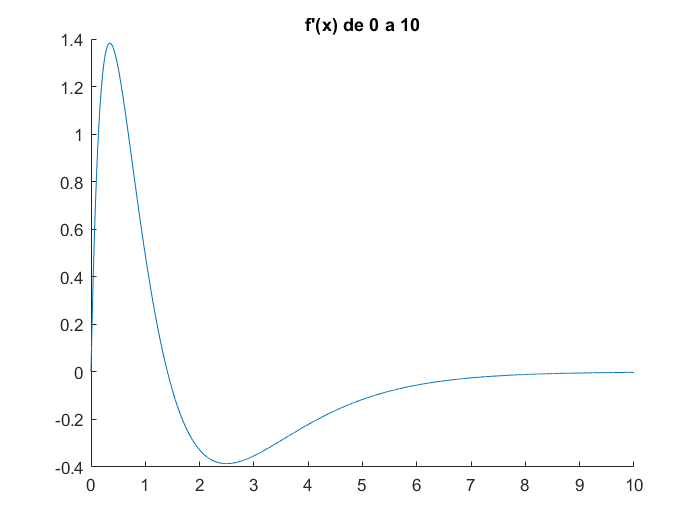

figure(5)
hold on
plot(z,dF(z));
title("f'(x) de 0 a 10");
hold off

Y observamos como, efectivamente, tiene un único cero en $(v,\infty)$ y ninguno en $(0,v)$.

#### 4-

Por último, a pesar de que vemos que f se va acercando a 0 hasta 10, vamos a verlo para mayores valores, hasta 1000, y quedarnos más tranquilos:

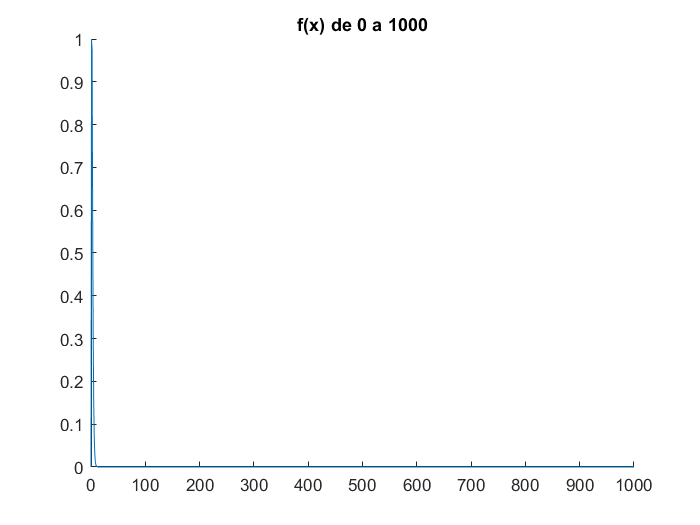

X = 0:1000;

figure(6)
hold on
plot(X,f(X));
title("f(x) de 0 a 1000");
hold off

Y se observa que se va hacia 0.

Por último, para conjeturar el resultado esperado, notamos primero que no tiene sentido pensar en x_n > 1, ya que estamos hablando de porcentajes. Por tanto, basándonos en las conclusiones del ejercicio 4.4, tenemos que:

- Si $0\leq x_0<0.3517$, entonces la población irá a 0 y desaparecerá.

- Si $0.3517\leq x_0 \leq 1$, entonces la población tenderá hacia el $0.996$% del límite poblacional.

Comprobemos estas conjeturas:

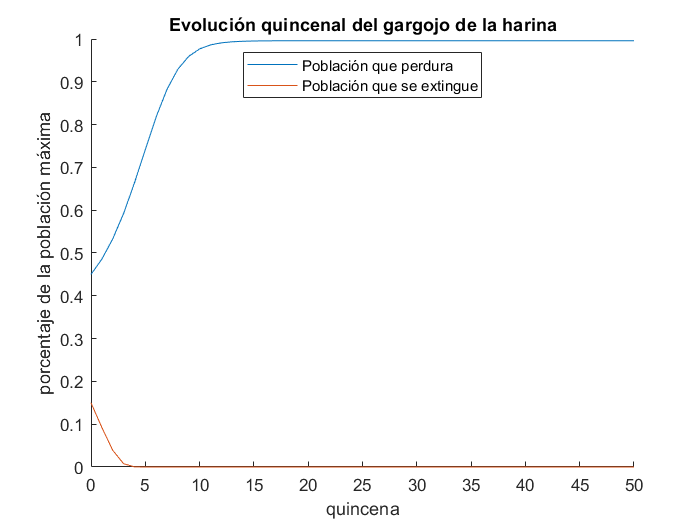

figure(7)
hold on
plot(0:50, iteracion(f,0.45,50))
plot(0:50, iteracion(f,0.15,50));
legend('Población que perdura', 'Población que se extingue', 'Location', 'north')
title('Evolución quincenal del gargojo de la harina')
xlabel('quincena')
ylabel('porcentaje de la población máxima')
hold off

Y comprobamos la veracidad (aparente) de las afirmaciones anteriores.